# 8. MATLAB meets Arduino

© B. Rasnow 1 June 25

## Objective

Explore more programming concepts and constructs to establish reliable high speed serial communication between MATLAB and Arduino, so we can build an oscilloscope. Note, I'm taking extra effort to not just give you a solution, but also show you *how* I developed the solution -- using documentation, dialog on the command line, and trial-and-error. Let's take this opportunity to also develop technical problem-solving skills.

## Introduction

Our last activity measured transistor gain and switching characteristics with the following Arduino software interface:

        Listing 1. Prior Arduino code prints 3 voltages per line ~ 5 times per second. 

We might explain the `loop` code in English as: "While Arduino pin D5 is grounded, print the voltage on A0, a tab character, the voltage on A1, a tab, the voltage on A2, and a new line character, then wait 1/5 second and do it again", where we don't really mean "print", but "send the data through the serial (USB) port". Grounding a jumper wire to D5 is a simple kluge of a human interface -- a $0 mechanical switch. 

That description alone doesn't explain how we *used* this code. Missing (or implicit) are invoking Arduino IDE's Serial Monitor (or Serial Plotter -- try it in the Tools menu), and copy/pasting from the Serial Monitor into MATLAB. Implicit with the instruction to "paste the data into MATLAB" is abiding by MATLAB's particular formatting requirement, e.g., 

Skipping any implicit step leads to failure. E.g., copy/pasting a few rows of data from Serial Monitor into MATLAB results in the following error message: 

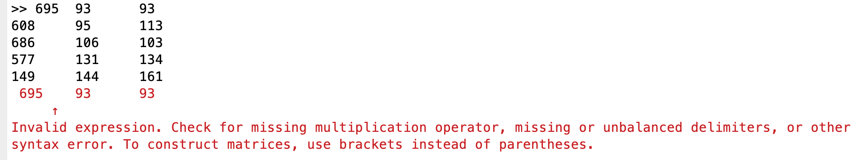

As you become a more experienced programmer, you learn to follow more implicit (unstated) instructions and also more quickly understand error messages. Some programming languages give more useful/meaningful error messages than others -- I think MATLAB is among the best in this regard. But as a novice, it is frustrating why "I did what I was told and it just won't work!". There are lots of implicit or shadow steps in engineering and science. 

### Automate formatting

We could automate some of the necessary formatting by adding a few lines to the Arduino program to print not just numbers, but MATLAB-executable code: 

        Listing 2. Listing 1 modified to print MATLAB-executable "source code" along with the data. 

Formatting strings are now printed with the data. You still have to copy and paste, but now you're pasting executable MATLAB code vs. just numerical data. Think of some reasons when and why this might be a good or a bad idea. 

### Creating a measure function

Consider this [refactored](https://en.wikipedia.org/wiki/Code_refactoring) version of the original Arduino code:

        Listing 3. Refactoring Listing 1 using a function to compartmentalize or abstract its functionality. 

Explain this code in English and contrast to the original version (which keep in mind does the *same* thing -- refactoring doesn't change *what *the code does, just *how *it does it). 

The new description defines a function called `measure` that neither takes nor returns any arguments (explicitly indicated by the keyword `void`). `setup` is the same and `loop` starts the same, "while pin 5 is grounded, `measure`". That's it!!!  We *abstracted* the details of measuring and printing, simply by putting them in function. Once we verify that this version works as expected, then it's easier to change details of `measure` with less chance of messing up something else. BTW, I debated where to put `delay(200);`. Is it part of (inside) `measure`, or "while pin 5 is grounded, measure and wait"? Little decisions like this pervade programming. I mainly opted for the former so I wouldn't need 2 curly {} on the` if` statement -- less code. 

### What *is* serial communication?

How does Arduino's Serial object work? Using one of the oldest (!) computer communication devices, a [Universal Asynchronous Receiver-Transmitter (UART)](https://en.wikipedia.org/wiki/Universal_asynchronous_receiver-transmitter). Why would we find such an antique among modern electronics? It's more of an abstraction, implemented anew with a (more) modern mix of logic, gates, software and firmware that does a most critical function: turn parallel data (where each bit's label or significance is encoded by its physical *location* into serial data (and visa versa), where each bit's significance is encoded in a *time* frame. Whereas (short) parallel data paths are efficient inside integrated circuits, serial data can achieve the same information flow in less space and cost -- by running faster ([multiplexing](https://en.wikipedia.org/wiki/Multiplexing)). The [Universal Serial Bus (USB)](https://www.edn.com/polishing-a-turd/) is one (of many) current serial standards ("a nice thing about standards is there are so many to choose from").  

Fun fact: the auditory systems of mammals maps sound frequency into a physical location or a "place code", via resonant amplification in the inner ear ([cochlea](https://en.wikipedia.org/wiki/Cochlea)). Owls localize sound arriving at one ear delayed by <1$\mu sec$ relative to their other ear using neurons with ~100 times more temporal jitter. The tiny interaural time difference is transduced by neural coincidence detectors and represented as a place code. So switching between temporal and spatial encoding schemes is common in both biological and silicon systems.

Nevertheless, Arduino's Serial implementation isn't great, and sometimes generates errors that we'll have to contend with. Switching to a more modern microcontroller like the [Raspberry pi Pico](https://en.wikipedia.org/wiki/Raspberry_Pi#Raspberry_Pi_Pico) or [Seeeduino XIAO](https://www.seeedstudio.com/Seeed-XIAO-RP2350-p-5944.html), the same C program executes  over 20 times faster and practically free of errors -- so its UART implementation is better. The Pico's brain (MPU) is an [RP2350](https://en.wikipedia.org/wiki/RP2350) with a dual 32 bit 150MHz ARM-Cortex-M33 processor vs. Arduino's 8 bit 16MHz [ATMega328](https://en.wikipedia.org/wiki/ATmega328) MPU (what a difference 10 years makes!). Further explanation of Arduino's UART is at [https://www.circuitbasics.com/how-to-set-up-uart-communication-for-arduino/.](https://www.circuitbasics.com/how-to-set-up-uart-communication-for-arduino) 

## Connecting MATLAB and Arduino

Our next task is to eliminate the manual copy/paste step by establishing a serial connection between MATLAB and Arduino. If you search the internet with keywords "matlab" and "arduino", the top hits will be about Mathwork's "Support Package for Arduino". This is interesting software to explore, but we won't be using it. First, it's really slow. The interface I'll show you moves data ~1000 times faster, and *when* you find that's too slow, our software runs >10 times faster on a XIAO or Raspberry pi Pico microcontroller than the Arduino. (You'll soon understand the insatiable "need for speed", if you haven't experienced it already in video games or elsewhere).

Second, by explicitly programming the Arduino and MATLAB, we can split tasks between them to further increase insatiable need for efficiency, speed, and capabilities. We also have more options to find and debug/remove inefficiencies. And third, it's actually *not* so complicated and it teaches us general programming and automation principles. 

As far as I know, the system we're building isn't described elsewhere in any one place. I've engineered this interface from bits of experience from decades of academia, biotech, small business, etc. I didn't invent it all -- I probably invented very little of it. So if you have questions, maybe about implicit steps I forgot to mention explicitly, ask me (e.g., drop me a terse email).  

So to be clear, we're NOT using Mathwork's "Support Package for Arduino". Instead we'll program the Arduino as before in C using its IDE. We'll pair each `Serial.print, ` `Serial.write` and `Serial.read` on the Arduino with corresponding MATLAB functions that use MATLAB's `serialport` object to send and receive the corresponding data, which will provide orders of magnitude faster performance tailored to our needs.  

### Serial ports cannot be shared

Windows, Unix, MacOS don’t allow multiple processes (active programs) to share serial ports. This means if the Arduino IDE is connected to the Arduino, then attempting to connect the Arduino to MATLAB results in this error (on MacOS or Linux): 

 

The solution is to either quit the Arduino IDE, or select Tools --> Port --> some device other than the Arduino. 

Likewise if MATLAB is connected to the Arduino and you try to program it in the IDE, the IDE will throw an error like: 

Key clue is "`ser_open(): can't open device`". The solution is in MATLAB, 

`>> clear ard` 

frees the serial port. (And compare the clarity of these two error messages, the first from MATLAB, the 2nd from Arduino's IDE). 

### Connecting the Arduino to MATLAB

We're going to interface MATLAB with Arduino using MATLAB's `serialport` object. Learn more about it by exploring: 

doc serialport

This replaced a previous `serial` object Mathworks provided prior to version 2019b. 

ports = serialportlist

returns a list of all serial ports. On Windows, the returned character strings will look like "COM4", and on MacOS and Linux, like "/dev/tty.usbserial…" which shows just the first part of a long name. So which one is the Arduino? There are complex handshake protocols to query USB devices for their ID. My goal here is the quickest, simplest, solution, which is trial and error. Unplug the Arduino and see which one disappears. Let me know if you figure out a simpler/better method. It turns out on my MacbookPro, the Arduino is *always *(so far) the last one in the list. So I just do the following, living dangerous in that this trick may stop working at any time, at which point I will look for another trick. Sorry I can't offer you a better (i.e., robust *and* simple) solution. This kind of kluging and short-cutting -- getting the task (in this case connecting to Arduino) done with minimal effort vs. e.g., maximal robustness -- is really useful in building simpler apparatus for non-critical tasks. If this stops working, curse and debug it. This kind of programming is totally inappropriate for "mission-critical" applications where failure can result in death or destruction, e.g., in flight control systems or autonomous EV's. So I think the kluge below is ugly, but I'm also proud of it. 

ard = serialport(ports(end),9600)

ports = 1×6 string array
    "/dev/cu.debug-console"    "/dev/tty.debug-console"    "/dev/cu.Bluetooth-Incoming-Port"    "/dev/tty.Bluetooth-Incoming-Port"    "/dev/cu.usbserial-3140"    "/dev/tty.usbserial-3140"

% or on Windows, if you find your Arduino is e.g., COM5 then:
% ard = serialport('COM5',9600)

ard =   Serialport with properties:

                 Port: "/dev/tty.usbserial-3140"
             BaudRate: 9600
                  Tag: ""
    NumBytesAvailable: 0
  Show all properties, functions


If you run this command a second time, it will generate an error -- because the serial port is already in use (by this program). `>> clear ard` will free it. The following code will only attempt initialization if the variable `ard` doesn't exist in the workspace:

if ~exist('ard','var') 
    ports = serialportlist; 
    ard = serialport(ports(end), 9600); 
end

Adding a Section Break in this LiveScript also lets us run the above code just once by moving the cursor to other sections and clicking "Run Section" instead of "Run". 

My Arduino is loaded with the Transistor software, that prints tab-separated columns of A0, A1,A2 at ~5 rows per second, when D5 is grounded. So I'll run the program (by grounding D5 and turning the LM317's R2 to collect a data set. Afterwards, type the following command:

ard.NumBytesAvailable

ans = 858

### Reading the data

So we have data. How to read it? Look at the `>> doc serialport `help page, on the left are Examples, and also "Read and Write Properties" that suggest: 

data = readline(ard)

data =     "1023	90	89
     "

Again, looks promising, although data is in quotes, suggesting a string. Can you figure out how to convert a string to numbers in MATLAB? 

data2 = str2num(data)

data2 =         1023          90          89


data2 = sscanf(data,'%d')'

data2 =         1023          90          89


Either of the above work, `sscanf` has security advantages according to the docs. Where did the transpose (') come from? Trial and error. By default, `sscanf` produced a column vector rather than a row vector, so transpose (') flipped it. If you're unsure about the data type and size,

whos data*

  Name       Size            Bytes  Class     Attributes

  data       1x1               174  string              
  data2      1x3                24  double              



That's the first line but there's still more data in the serial buffer, how much more? 

ard.NumBytesAvailable

ans = 478

Get the rest of the data in a loop:

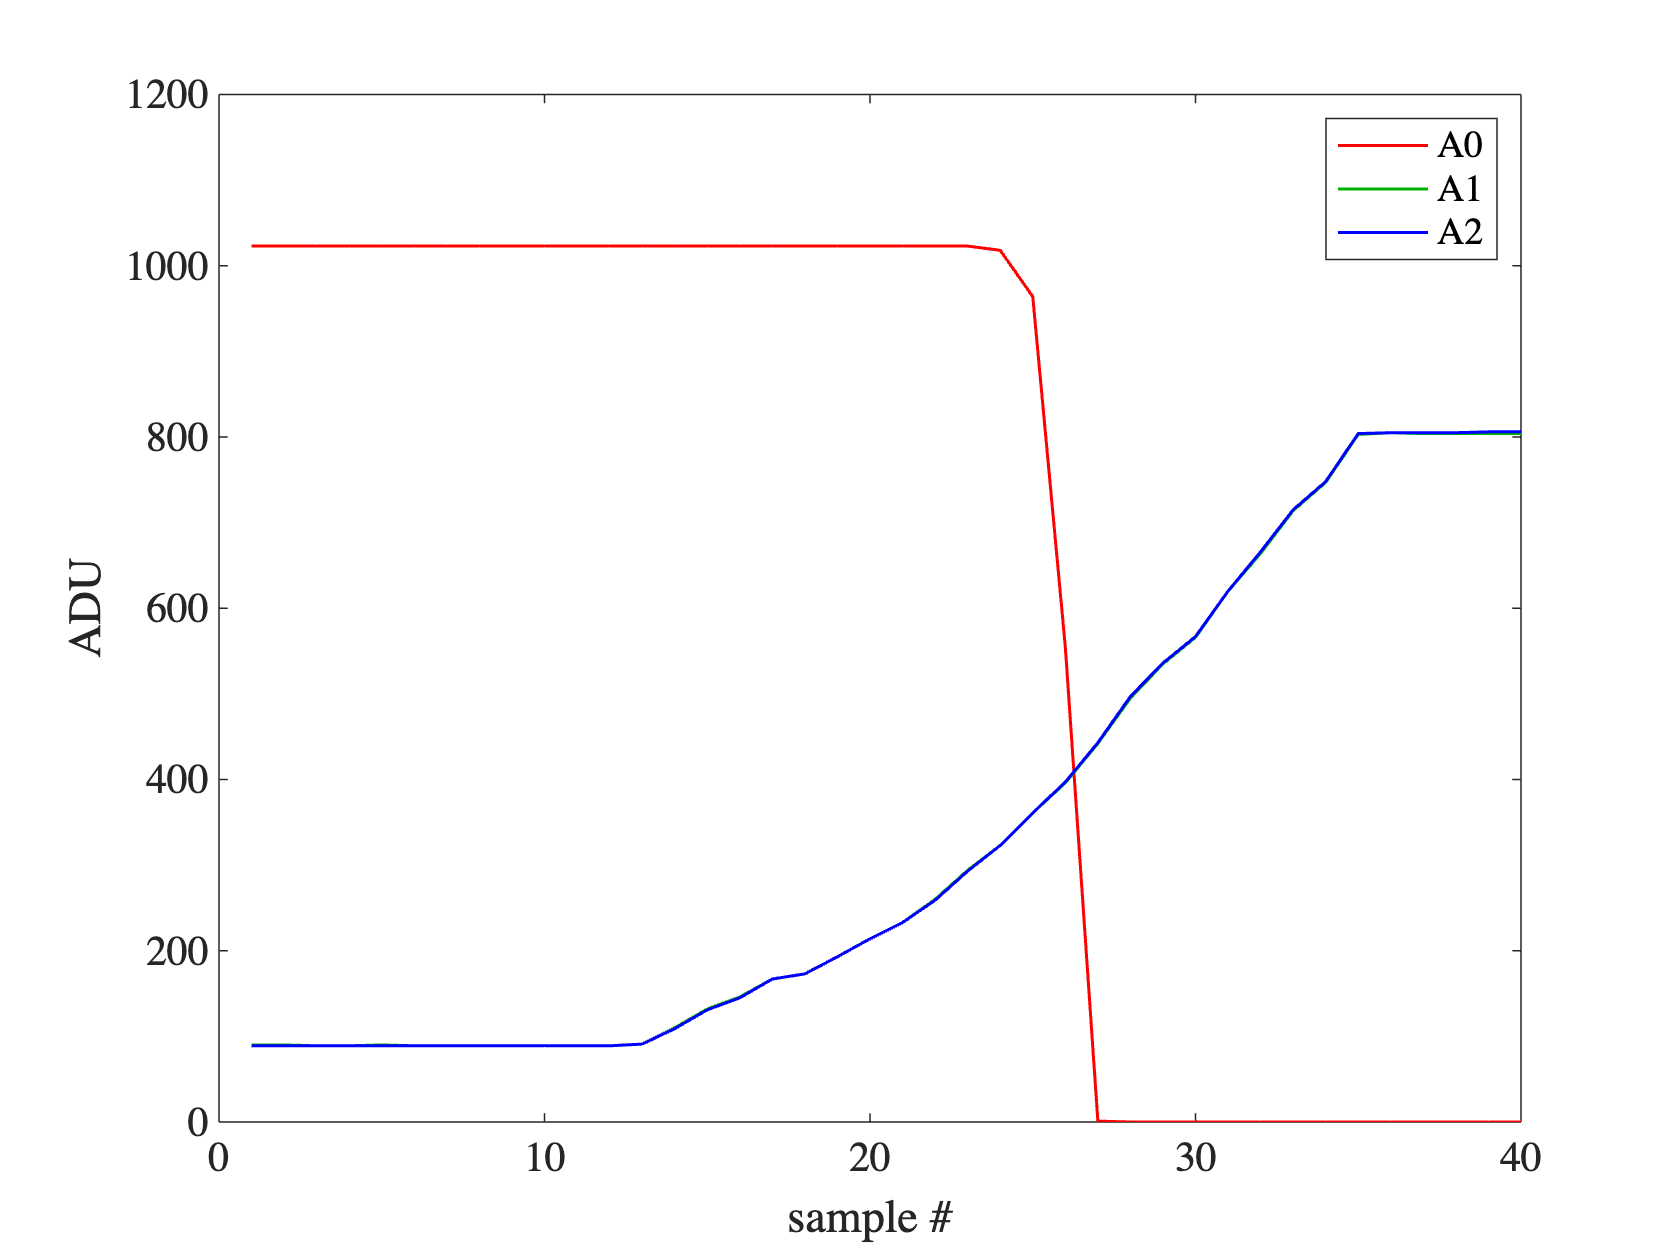

i = 1; % we read the first line above
while ard.NumBytesAvailable > 0
    i = i+1;
    data2(i,:) = sscanf(readline(ard),'%d')';
end
plot(data2); xlabel('sample #'); ylabel('ADU'); legend('A0','A1','A2')

Credible? Notice how easy it is to verify the data using plot, rather than poking around at a pile of numbers. We could just as easily continue, plotting `ic` vs `ib` and computing beta. (BTW, where is A1? It's "under" A2, the two are virtually identical because the DUT is the MOSFET with practically zero gate current.)

### Adding a command parser

How will MATLAB know when data is available? Instead of toggling data with a human interface via the D5 jumper to ground "switch", MATLAB can request data via the serial interface if the Arduino is programmed to listen. Soon we'll want the Arduino to do more than just return data, so a "command parser" will enable MATLAB and Arduino to exchange multiple kinds of information, but it's up to us (programmers) to ensure each side of the serial link follows consistent rules. Here's an Arduino program that does a measurement upon receiving an 'm' command from MATLAB:

        Listing 4. Arduino reads and responds to a serial command. 

A couple of instructions were added to setup -- `flush()` clears any prior data in the serial buffer (think toilet). I was going to say that `measure()` didn't change but it did -- I took out `delay()`, which isn't an essential aspect of measuring. If we want 5 measurements per second, use MATLAB's `pause()`. Note: MATLAB's `pause(seconds)` vs. Arduino's `delay(msec)` use different units. The D5 "switch" was removed, as MATLAB will now control when data is measured and sent. 

I opted for compact code (i.e., not using a `case` statement nor checking for errors). Even so, I had to iterate a few times, moving the Arduino back and forth between IDE and MATLAB. Test this code in Arduino's IDE's Serial Monitor: send an m and verify you get back A0\tA1\tA2\n. 

Don't proceed until it's debugged and verified in the IDE.

Then test it in a MATLAB loop, but first free the Arduino from the IDE (Tools --> Port --> uncheck Arduino, and then connect MATLAB to the Arduino:

>>  `ard = serialport(ports(end), 9600); `

How fast we can measure using this interface? MATLAB's timer functions `tic` and `toc` measure elapsed time:

n = 100;
data = zeros(n,3); % preallocate storage
tic; 
for i=1:n, writeline(ard, 'm'); data(i,:) = sscanf(readline(ard),'%d')'; end
toc

Elapsed time is 1.785571 seconds.


If we want 10 measurements per second, i.e., want this to take 10 seconds instead of ~2 seconds, we need to add a delay ~8 seconds or 8/n seconds per iteration. After executing the code below, turn LM317's R2 slowly for 10 seconds:

data = zeros(n,3); % start clean
tic; for i=1:n
    writeline(ard, 'm'); 
    data(i,:) = sscanf(readline(ard),'%d')'; 
    pause(8/n); 
end, toc

Elapsed time is 9.915954 seconds.


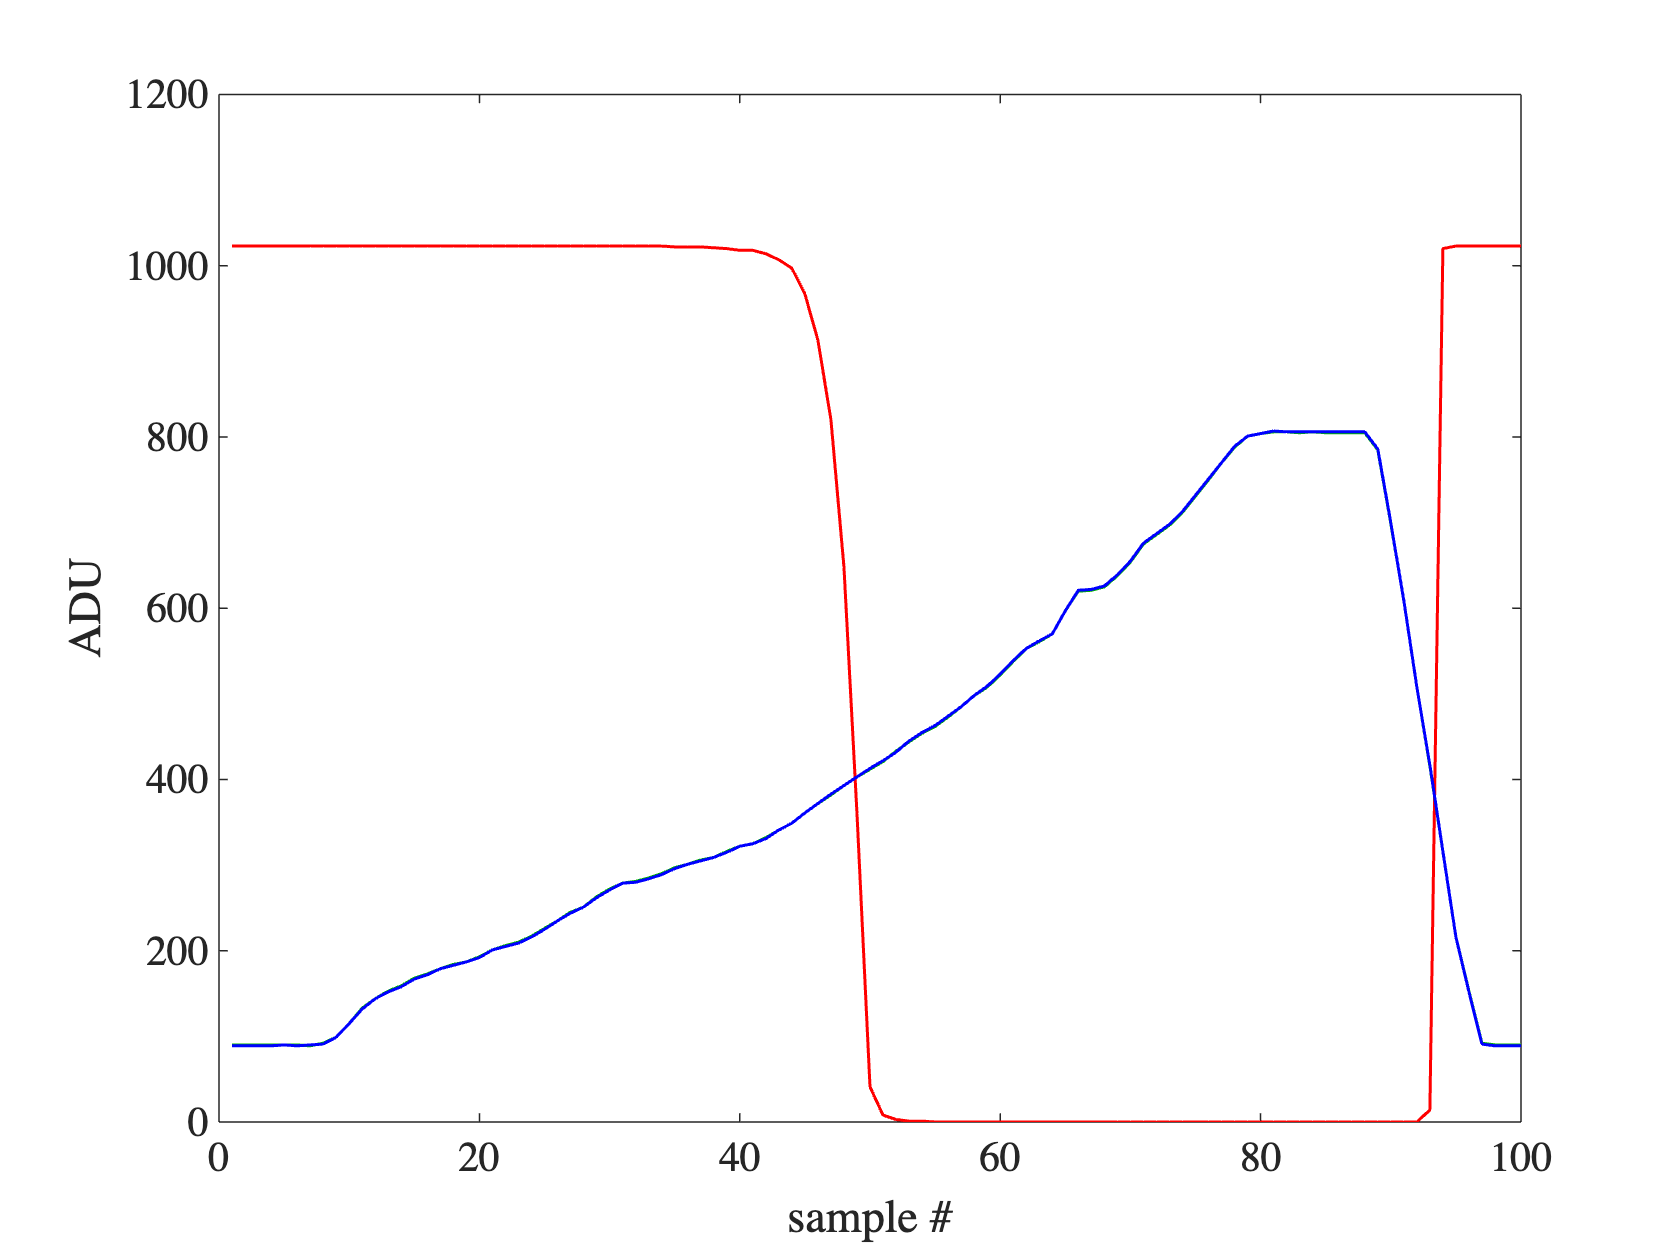

plot(data); xlabel('sample #'); ylabel('ADU')

If you didn't read valid data above, then DON'T proceed until you debug and get the system working, because it's about to get much harder to debug. 

### Binary Data Format

We've been sending data so far in "ASCII format" where a byte (or 2 bytes, called "unicode") represent each character read or typed. A drawback of ASCII is the numbers 9 and 10 are different lengths. So we can't tell know how many numbers are in an e.g., 476 byte buffer. Alternately we could format each ADU value as two bytes (as it's stored in type `int16`). `Serial.print` won't have to convert each `int16` value into ASCII before sending, nor add and send tab and return characters to separate each number.  Binary data is thus more efficient for the computer to write and read, but it's harder for us humans to read and debug. Here's a binary version of the previous code: 

        Listing 5. Arduino code sends binary encoded data  to MATLAB.

To keep it simpler, I didn't support both formats, e.g., send ASCII with an "m" command and binary with a "b" command, but I changed the command to a 'b' for clarity. You're welcome to implement both. Soon we'll replace the `if` statement with a `case` statement that supports an expandable command set. Trying this a few times in the IDE Serial Monitor produces gibberish, because binary doesn't display usefully in Serial Monitor (welcome to "[The Matrix](https://www.themeatrix.com)"): 

To read it in MATLAB, switch the Arduino over (close Serial Monitor, Tools --> Port --> something else; `>> ard =` up arrow), and try the following (don't forget to change the 'm' to a 'b' command: 

data = zeros(n,3);
tic; for i=1:n, writeline(ard, 'b'); data(i,:) = read(ard, 3,'uint16'); end, toc

Elapsed time is 1.161562 seconds.


Binary runs about 50% faster on this computer (yours will likely be different), so make the delay appropriately longer:

data = zeros(n,3);
tic; for i=1:n, writeline(ard, 'b'); data(i,:) = read(ard, 3, 'uint16'); pause(9/n); end, toc

Elapsed time is 10.254847 seconds.


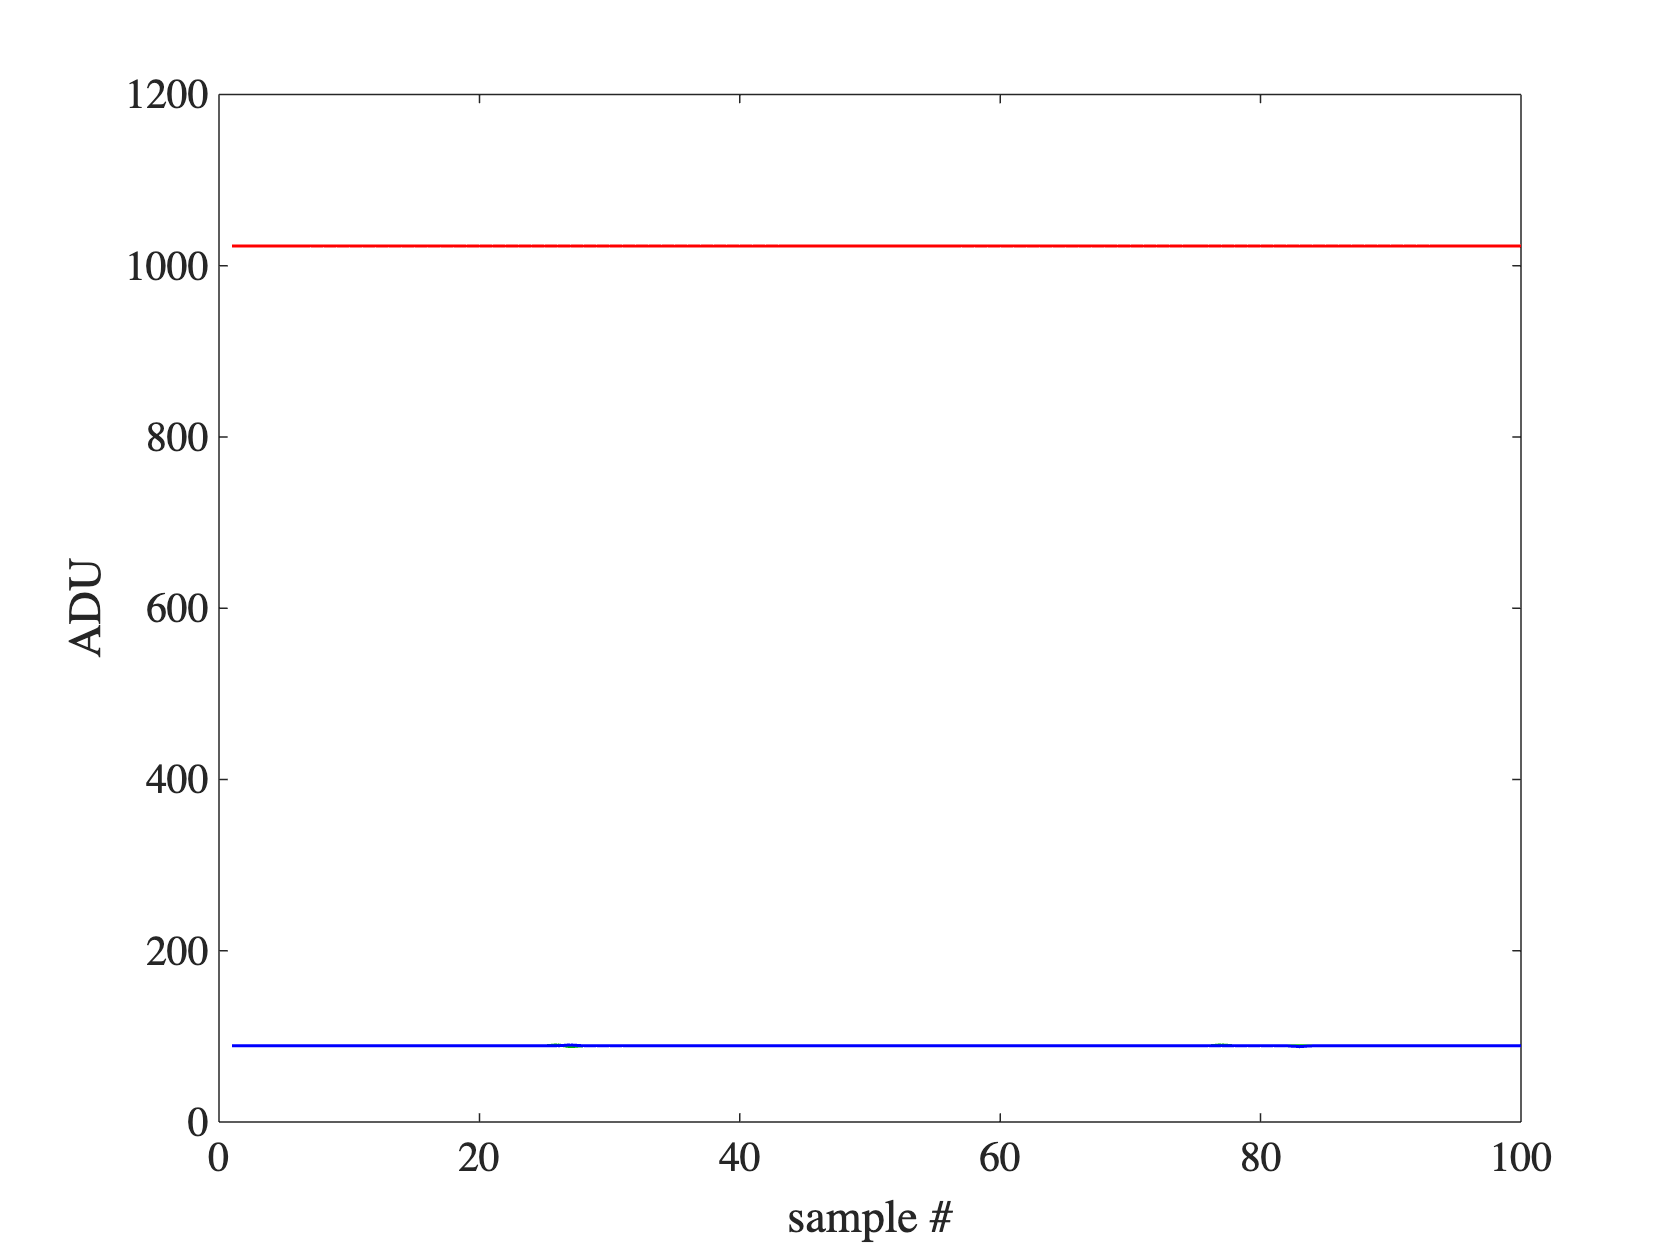

plot(data); xlabel('sample #'); ylabel('ADU')

Is the data ok? Don't proceed until you've debugged the system and convinced yourself it's working properly. (What tests are you requiring?)

## oscope1.ino -- our final Arduino program

We learn about computers by exploring and conversing with them, and I hope some of the above explorations and conversations on the command line gave you ideas on how to make fruitful conversations in other contexts. After many iterations, explorations, conversations, trial and error, ... I converged on the following Arduino program that we'll use for the rest of the semester -- unless we find new reasons to change it. Putting heavy consideration on simplicity, it supports just 2 commands. 

        Listing 6. `oscope1.ino`, our final Arduino program that `analogWrite`s and measures 400x2 sequential voltages on A0 and A1. 

Study it and note the significant changes. E.g., 

- The serial port speed is jacked way up to 115200/2 baud. I worked my way up to this speed, and have reliably issues at higher speed. "Your mileage may vary", dividing the baud rate by 2 may produce more reliable (and slower) communication on your computer.

- Pin D5 is now an analog output (that we'll use later to program the LM317 voltage and our function generator's frequency) -- recall earlier we had configured D5 as an input. Welcome to "programmable logic", it is what you say it is. 

- The 'p' command `analogWrite`'s an integer it reads from the serial port, constrained between 0-255, to pin D5.

- The 'b' command is similar to the above measure() function, but key differences are that it measures two pins, A0 and A1, and it repeats each 400 times as fast as it can. How fast? It times itself and returns the elapsed measurement time (in microseconds) along with the data. Why 400 repetitions? Enough to make a nice plot, and use almost all of Arduino's memory (Arduino's IDE gives a "Low memory available ..." warning that there's just ~250 more bytes available Note that there is *less* than that -- as local variables like pwmVal and the Serial object use this memory too).

- The data is structured A0 A1 A0 A1 ... A0 A1 (400 pairs), followed by least and most significant 16 bits of elapsed microseconds.

- All the data is written with one `Serial.write()` command. `data` is "typecast" as `uint8_t*` (read "uint 8 underscore t pointer") because that's the only data type that `Serial.write` knows how to send. It doesn't matter that the data is really of type u`int16` -- just that on the other side, MATLAB will read it as such.

- The command parser is implemented with a more powerful and expandable `switch/case` construct.

## oscope1.m -- our first oscilloscope program

There are several ways we could write MATLAB software for the other side of the serial port. Starting simple, the software needs to 1) initialize the serial port and a figure window to display the data; 2) send an ascii 'b'; 3) read the binary Arduino data; 4) reformat it into MATLAB arrays that can be 5) plotted. This might be done with multiple functions, one function, a script, etc. I tested the commands one at a time on the command line, then combined them into a script, and finally put it together in the listing below, saved as oscope1.m. It's not the only way, and probably not the *best* way, so feel free to explore and refactor. 

        Listing 7. MATLAB file `oscope1.m`, interfaces with Arduino's `oscope1.ino` providing a real-time 2 channel oscilloscope display.

First, note the file is a script, not a function. So the variables exist (their scope is) in the main workspace. This makes it easier to debug (as long as one is careful not to overwrite them accidentally). The first block of the code is conditional initialization. If `runBtn` doesn't exist then create it as a `uicontrol`. `>> help uicontrol` or `>> doc uicontrol` to learn more. The next `if` block initializes the Arduino. On my Macbook Pro, the Arduino is always the last `port`, so that's what I open. If that doesn't work, then you'll have to explore how your computer identifies the Arduino and change this code accordingly, e.g., to the appropriate 'COM' port. Make certain the baud rates match the line in `setup()` on the Arduino. I specified the baud rate at 115200/2 = 57600 bits per second which works on most computers, and some can reliably communicate with Arduino at twice that speed. We're moving 1604 bytes ~ 16,000 bits (including temporal framing bits) in each iteration, which should take ~16000/57600 = 280 msec at the slower baud rate. Measuring the data on the Arduino also takes ~ 9msec, so the refresh rate or frame rate of the display will be ~ 3 frames/second, and nearly twice that at 115200 baud. 

The 3rd block loops while the `runBtn` is clicked, and implements a basic oscilloscope in 5 lines! It sends the Arduino a 'b', waits a few msec, then tries to read a block of (binary) data into variable `bin` formatted as u`int16` (2 byte numbers). The first 800 of these are `reshape`d into a 400 row by 2 column matrix, which is then `plot`ted. That's it.

Debug until it works, since the additional features and functions we'll soon add will make debugging harder. What's there to add? Calibrated time axis -- milliseconds instead of sample #. Robustness to serial communication errors that happen occasionally. Later we'll display amplitude vs. *frequency* on the x-axis as a spectrum analyzer does. With our function generator, we'll add triggering to stabilize the initial phase of AC waveforms, display measurements of amplitudes, frequency and phase, and correct some systematic errors in the data ("deskewing"). All those changes will be just on the MATLAB side, but starting simpler is a rational strategy.

## Conclusions

We've covered a lot of diverse terrain here. We started with [refactoring](https://en.wikipedia.org/wiki/Code_refactoring) the Arduino code -- rewriting the *code* without changing its behavior. Making it more modular made it easier/safer to change its behavior, first by adding a measure function, then adding a command parser, and finally changing the data format from ASCII to binary. Refactoring is best done in small steps that are tested and validated before attempting the next one, although that becomes tedious because serial ports can't be open at the same time by more than one application. We practiced moving back and forth between programming Arduino in the IDE and running Arduino from MATLAB. Switching from one to the other requires freeing the port, in MATLAB by` >> clear ard` and in the IDE by selecting a different port or device in the Tools menu. Debugging often requires many iterations of this process... 

In the end, we constructed a powerful data acquisition and control apparatus. How does this compare to MATLAB's Support Package for Arduino? My experience with the Support Package is limited -- because its capabilities are so limited compared to what we did here. I believe the advantage of the Support Package is you don't (can't) program the Arduino, the Package uploads a command set that communicates with corresponding MATLAB software. The fastest the Support Package can `analogRead` is ~20 samples per second, vs. our system reads data ~8928 samples per second, about 450 times faster -- and you'll soon see why we wish it were even faster. Our code is also highly portable, it runs (with small changes) on other microcontrollers compatible with the Arduino IDE (e.g., the [Raspberry pi Pico 2](https://www.raspberrypi.com/products/raspberry-pi-pico-2/) and [Seeeduino XIAO](https://www.seeedstudio.com/XIAO-RP2350.html)).

Switching data format from ASCII to binary was a huge change. It permitted measuring 800 voltages as fast a possible, moving the data in a single block transfer of predictable size, and eliminated tedious reformatting to ASCII using multiple `print` statements on the Arduino that essentially get undone with multiple `sscanf` statements on MATLAB. The cost of this efficiency is we can't see the data meaningfully in Serial Monitor, so debugging is more challenging now. 

Underlying all of this is the goal to automate mundane tasks that we previously did, like copy/pasting data between two programs, or messing with data formatting minutiae. The more of these steps we can program (once) the computer to do, the more efficiently we can work and think about the bigger picture -- what the data means, what the circuits are doing, etc. What other lessons have you gotten from this? 

## What's next?

There are many further improvements we could make, and I'll bet you can think of several. We could add an 'n' command to set the number of samples to return, instead of always 400; program what channels to sample instead of always A0 and A1, etc. The `switch/case` statement is very easy to extend. But I think it is likely that we won't need to make any changes to the Arduino code for the rest of the class! From this little microcontroller running these few lines of code, we'll build in MATLAB code a dual channel oscilloscope and spectrum analyzer for audio signals and a remarkably accurate AC voltmeter that measures both amplitudes and phases of sine waves. We'll also create MATLAB functions that will `setVoltage(volts)` of the LM317 output without us touching R2, and `setFrequency(Hz)` of our function generator. Those will work by sending Arduino `'p'` commands, and routing signals through interface hardware and software that we'll spend the next few weeks designing, prototyping, and building. 

**Discussion question: **

Which of these is better code, and why? 

## Appendix: isvalid.m

If you don't have an `isvalid` function (current Octave doesn't), here's one to put in your toolbox: 